# Table I - MATA

## Preprocessing

### convertImagesInDirectory

Filters for MLO image type, converts images from PNG's to JPG's, and flips the image based on image orientation.

%  nameNoExt = split(files(i).name, '.');
%     parsedName = split(nameNoExt{1}, '_');
%     if strcmp(parsedName{4}, 'MLO')
%         img = imread(files(i).name);
%         img = im2gray(img);
%         if strcmp(parsedName{2}, 'L')
%             img = fliplr(img);
%         end
%         count = count + 1;
%         filename = strcat(output_folder, "cdd-", string(count), ".jpg");
%         imwrite(img, filename, "jpg");
%     end

### createDataTable

Creates a datatable based on csv datasheet classification

% if strcmp(dataTable.Type{i}, 'CESM') && strcmp(dataTable.View{i}, 'MLO')
%         count = count + 1;
%         CDDTable.ID(count) = count;
%         if strcmp(dataTable.Classification{i}, 'Malignant')
%             CDDTable.Class(count) = 'M';
%         elseif  strcmp(dataTable.Classification{i}, 'Benign')
%             CDDTable.Class(count) = 'B';
%         else
%             CDDTable.Class(count) = 'N';
%         end
%     end
CDDcsvTable = readtable('CDD-Data.csv')

CDDcsvTable = 503×2 table
    ID    Class
    __    _____

     1    {'M'}
     2    {'B'}
     3    {'B'}
     4    {'M'}
     5    {'B'}
     6    {'N'}
     7    {'N'}
     8    {'N'}
     9    {'B'}
    10    {'N'}
    11    {'M'}
    12    {'N'}
    13    {'N'}
    14    {'B'}
    15    {'B'}
    16    {'B'}


## Machine Learning

### resizeMachineLearn

Resizes every image to 227 by 227 to fit deep learning net

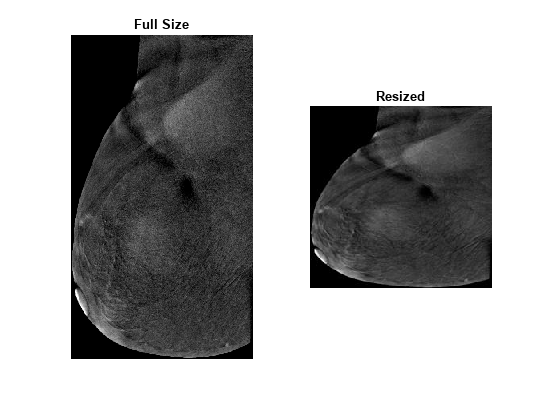

figure
subplot(1, 2, 1);
imshow('dataset/full/CDD/cdd-1.jpg');
title('Full Size');
subplot(1, 2, 2);
imshow('dataset/processed/CDD/cdd-1.jpg');
title('Resized');

### splitByClass

Uses previous datatable to split images by cancerous vs non-cancerous

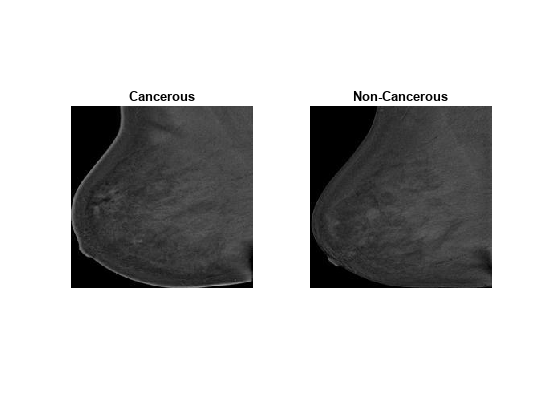

figure
subplot(1, 2, 1);
imshow("dataset\split\CDD\Cancerous\cdd-100.jpg");
title('Cancerous');
subplot(1, 2, 2);
imshow("dataset\split\CDD\Non-Cancerous\cdd-101.jpg");
title('Non-Cancerous');

### machineLearnScript

Allocates training and testing data to use within neural network

disp(CDDcsvTable)

    ID     Class
    ___    _____

      1    {'M'}
      2    {'B'}
      3    {'B'}
      4    {'M'}
      5    {'B'}
      6    {'N'}
      7    {'N'}
      8    {'N'}
      9    {'B'}
     10    {'N'}
     11    {'M'}
     12    {'N'}
     13    {'N'}
     14    {'B'}
     15    {'B'}
     16    {'B'}
     17    {'N'}
     18    {'M'}
     19    {'N'}
     20    {'B'}
     21    {'B'}
     22    {'N'}
     23    {'M'}
     24    {'N'}
     25    {'B'}
     26    {'B'}
     27    {'M'}
     28    {'N'}
     29    {'B'}
     30    {'B'}
     31    {'B'}
     32    {'N'}
     33    {'M'}
     34    {'N'}
     35    {'B'}
     36    {'M'}
     37    {'M'}
     38    {'B'}
     39    {'M'}
     40    {'N'}
     41    {'N'}
     42    {'N'}
     43    {'B'}
     44    {'B'}
     45    {'M'}
     46    {'N'}
     47    {'N'}
     48    {'M'}
     49    {'B'}
     50    {'B'}
     51    {'N'}
     52    {'N'}
     53    {'

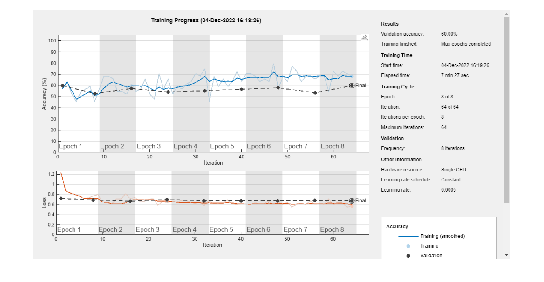

figure
imshow('neuralNets\data\raw_1.png')

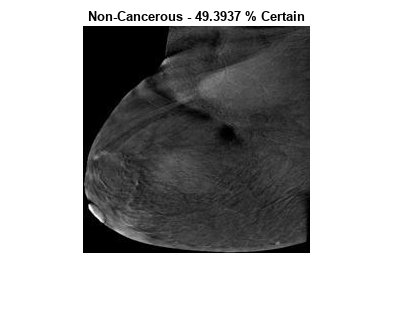


[predictions, probability] = classify(trainedNetwork_5, testSet);
figure
imshow(testSet.Files{1});
title(strcat(string(predictions(1)), " - ", string(probability(1) * 100), " % Certain"));

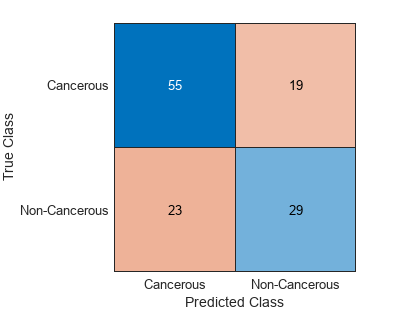

confusionchart(testSet.Labels, predictions);